# Matched Filtering of Linear FM Waveform

This example compares the results of matched filtering with and without spectrum weighting. Spectrum weighting is often used with linear FM waveforms to reduce the sidelobes in the time domain.

**Note:** This example runs only in R2016b or later. If you are using an earlier release, replace each call to the function with the equivalent `step` syntax. For example, replace `myObject(x)` with `step(myObject,x)`.

Create a linear FM waveform with a duration of 0.1 milliseconds, a sweep bandwidth of 100 kHz, and a pulse repetition frequency of 5 kHz. Add noise to the linear FM pulse and filter the noisy signal using a matched filter. This example applies a matched filter with and without spectrum weighting.

Specify the waveform.

waveform = phased.LinearFMWaveform('PulseWidth',1e-4,'PRF',5e3,...
    'SampleRate',1e6,'OutputFormat','Pulses','NumPulses',1,...
    'SweepBandwidth',1e5);
wav = getMatchedFilter(waveform);

Create a matched filter with no spectrum weighting, and a matched filter that uses a Taylor window for spectrum weighting.

filter = phased.MatchedFilter('Coefficients',wav);
taylorfilter = phased.MatchedFilter('Coefficients',wav,...
    'SpectrumWindow','Taylor');

Create the signal and add noise.

sig = waveform();
rng(17)
x = sig + 0.5*(randn(length(sig),1) + 1j*randn(length(sig),1));

Filter the noisy signal separately with each of the filters.

y = filter(x);
y_taylor = taylorfilter(x);

Plot the real parts of the waveform and noisy signal.

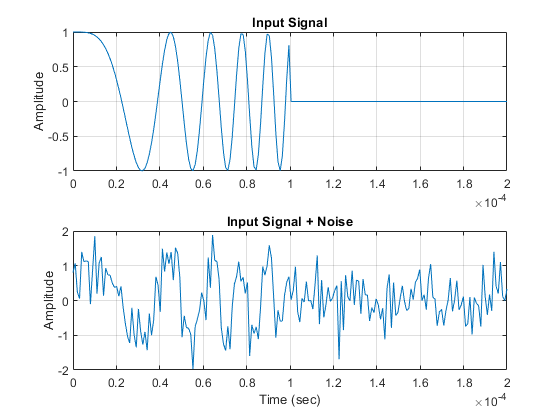

t = linspace(0,numel(sig)/waveform.SampleRate,...
    waveform.SampleRate/waveform.PRF);
subplot(2,1,1)
plot(t,real(sig))
title('Input Signal')
xlim([0 max(t)])
grid on
ylabel('Amplitude')
subplot(2,1,2)
plot(t,real(x))
title('Input Signal + Noise')
xlim([0 max(t)])
grid on
xlabel('Time (sec)')
ylabel('Amplitude')

Plot the magnitudes of the two matched filter outputs.

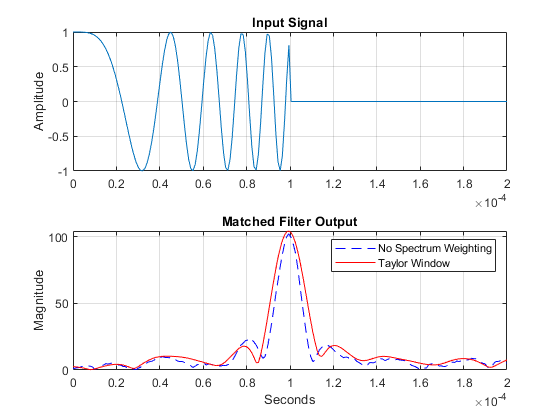

plot(t,abs(y),'b--')
title('Matched Filter Output')
xlim([0 max(t)])
grid on
hold on
plot(t,abs(y_taylor),'r-')
ylabel('Magnitude')
xlabel('Seconds')
legend('No Spectrum Weighting','Taylor Window')
hold off

*Copyright 2012 The MathWorks, Inc.*